clc; clear all; close all;

## Echo filter

% 100 ms pri 44100 fs je 4410
% 100*44100/1000
fvtool([1 zeros(1, 4410) 0.5], 1)

Kdyz to budu delat pres filter, tak to ustrihne konec, kterej by mel vzniknout.

Pres conv to necha ozvenovej cancourek - dozvuk filtru.

Kdyz chci cancourek z filtru, tak si musim ulozit i navratovou hodnotu Zf, ve ktere je ulozen cancourek.

Echo je ale nesmyslne realizovat pres konvoluci - az moc nasobeni nulama.

### Nekolik ozven

Nekonecna ozvena muze byt realizovana IIR filtrem.

Ale g musi byt mensi jedne, aby ozvena klesala do nekonecna.

fvtool(1, [1 zeros(1, 4410) -0.5])

Na IIR realizaci potrebujeme stejne pameti.

Nemuzu udelat takhle ruzny ozveny - vzdy bude stejne zesileni a stejne zpozdeni.

clc; clear all; close all;

## Reverb

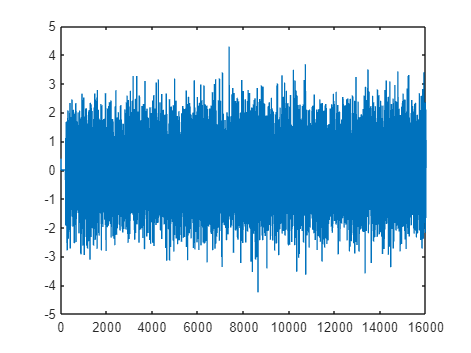

[zpev, fs] = audioread("female_anechoic.wav");
h = randn(1, fs);
h(2:200) = 0;
g = h .* (1./((1:fs).^0.6));
plot(h)

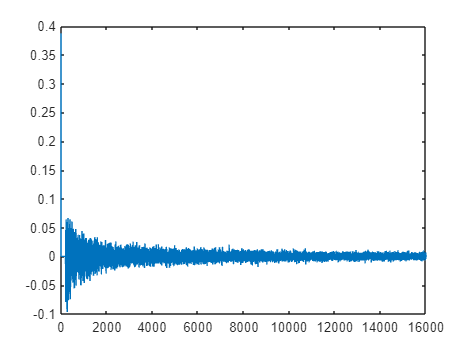

plot(g)

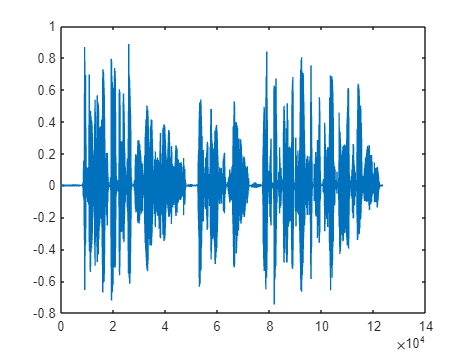

plot(zpev)

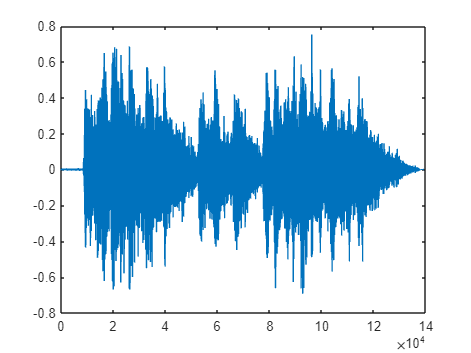

y = conv(zpev, g);
plot(y)

soundsc(y, fs)

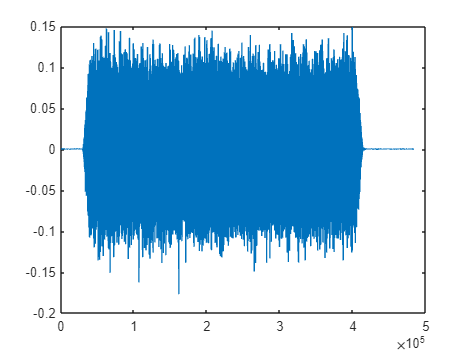

clc; clear all; close all;
[zpev, fs] = audioread("WN_t60-600_onspeaker.flac");
plot(zpev)

[x_arr, fs_arr] = audioread("WN_t60-600_array3.flac");
s = resample(zpev, fs_arr, fs);
plot(s)

miso_firwiener pocita impulsni odezvu v mistnosti 

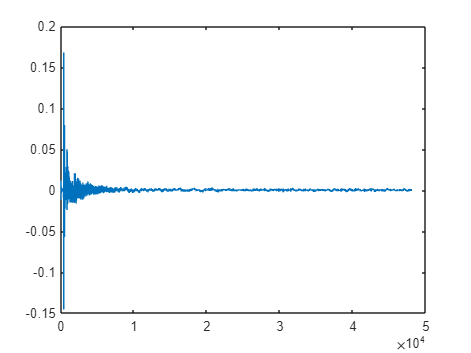

h = miso_firwiener(fs_arr, zpev, x_arr(:, 1));
plot(h)

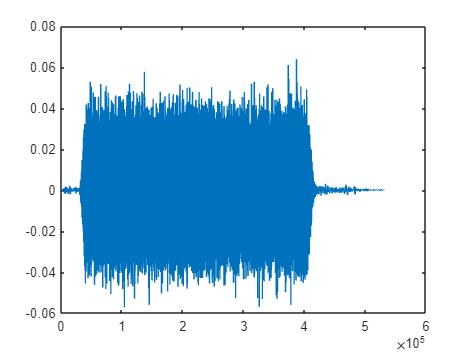

y = conv(s, h);
plot(y)

soundsc(y, fs_arr)

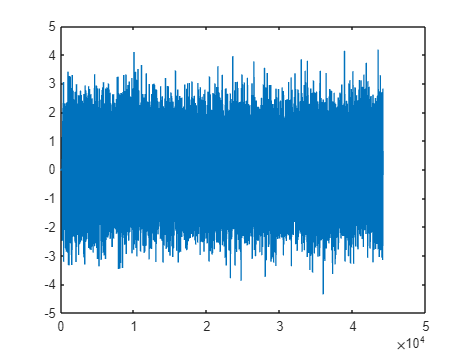

clc; clear all; close all;
[doprovod, fs] = audioread("chtit jen malo doprovod.wav");
[zpev, fs] = audioread("chtit jen malo zpev bez delay a reverb.wav");
h = randn(1, fs);
h(2:200) = 0;
g = h .* (1./((1:fs).^0.6));
plot(h)

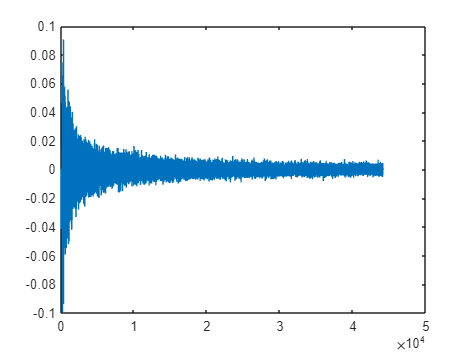

plot(g)

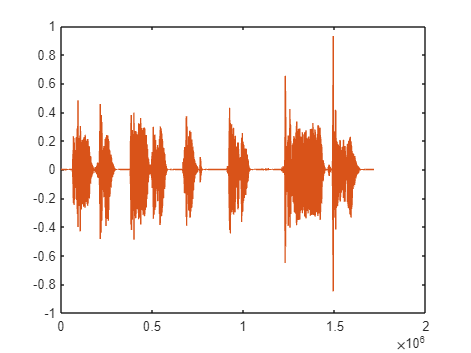

plot(zpev)

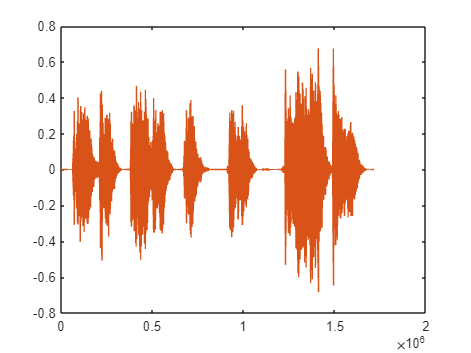

y = filter(g, 1, zpev);
plot(y)

soundsc(doprovod + y, fs)